# Portfolio Theory Management Assignment

We have retrieved the stock price data from Yahoo Finance. Now, we will construct two portfolios; one uses the Mean-Variance model, and the other one uses the Black-Litterman model.

## The Mean-Variance and Naïve Models

% First, we'll start with the Mean-Variance model.
% To begin, we will read the stock price data.
clear all
warning('off', 'all');

T = readtable('stock_data.csv');
T(1:5, 2:end)

ans = 5×15 table
     TSLA      CVX       JNJ       AAPL      JPM       AVGO       HD        PG       CRM        PM       PFE       AMZN      NKE       BLK        V   
    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    37.845    76.956    214.79    341.52    135.55    87.876    152.43    110.74    84.812    70.124     33.39    79.923    50.893    20.675    128.22
    34.075    75.01

Now that we got the prices, we proceed with calculating the expected returns, covariance matrix, and correlation matrix of the stocks.

% Next, we calculate the returns of stock prices.
% We use the continuous method to compute the logarithmic returns.
returns = tick2ret(T(:, 2:end), "Method", "continuous");
symbols = T.Properties.VariableNames(2:end);

% Create a Portfolio Object to get the means and covariances of the returns.
p_mean_var = Portfolio('AssetList', symbols, 'RiskFreeRate', 0.05);

% Get the mean and covariance (multiply by number of trading days)
m = mean(returns.Variables) * 252;
c = cov(returns.Variables) * 252;
disp(array2table(m, 'VariableNames', symbols));

     TSLA        CVX       JNJ       AAPL        JPM       AVGO       HD          PG         CRM         PM          PFE        AMZN        NKE        BLK         V   
    _______    _______    ______    _______    _______    ______    _______    ________    _______    ________    _________    _______    _______    _______    _______

    0.32587    0.13637    0.3304    0.17359    0.13299    0.1039    0.16465    0.068133    0.13829    0.086919    -0.032712    0.12027    0.12318    0.49

disp(array2table(c, 'VariableNames', symbols, 'RowNames', symbols));

              TSLA        CVX         JNJ         AAPL        JPM         AVGO         HD          PG         CRM          PM         PFE         AMZN        NKE         BLK          V    
            ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________    ________

    TSLA       0.104    0.070512    0.078102    0.062801    0.071049    0.041521    0.053816  

% Finally, get the correlation matrix
cor = corr(returns.Variables);
disp(array2table(cor, 'VariableNames', symbols, 'RowNames', symbols));

             TSLA        CVX        JNJ       AAPL        JPM       AVGO        HD         PG         CRM        PM         PFE       AMZN        NKE        BLK         V   
            _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______

    TSLA          1    0.62091      0.656    0.61276    0.57712    0.35994    0.57749    0.40565    0.45839    0.53537    0.

% Set the previously collected mean and variance as Moments
p_mean_var = setAssetMoments(p_mean_var, m, c);

First, we need a basis of comparison. We create a naïve portfolio (a portfolio with equal weights) and use it as the basis. We estimate the mean and standard deviation of the naïve portfolio using the estimatePortMoments function.

p_naive = setInitPort(p_mean_var, 1/p_mean_var.NumAssets);
[nrsk, nret] = estimatePortMoments(p_naive, p_naive.InitPort);

% Display the results
disp(strcat("Naïve Portfolio Expected Return: ", string(nret)));

Naïve Portfolio Expected Return: 0.16746


disp(strcat("Naïve Portfolio Risk: ", string(nrsk)));

Naïve Portfolio Risk: 0.22316


Because the method to calculate the mean return and covariance is the same for the Naïve model, we proceed with the next step.

Next, we construct a mean-variance portfolio and proceed with estimating the covariance, variance-covariance, and correlation matrices.

% Set portfolio constrains and run portfolio optimization
p_mean_var = setDefaultConstraints(p_mean_var);
p_mean_var = Portfolio(p_mean_var, 'LowerBound', 0.05);

Now, we plot the efficient frontier. We use the estimateFrontier function to estimate a frontier consisting of 30 portfolios. Since our target is to beat the benchmark, we will set the target return to be 20% (higher than the average return of the S&P500 from 2019-2023, which is currently 14.68%).

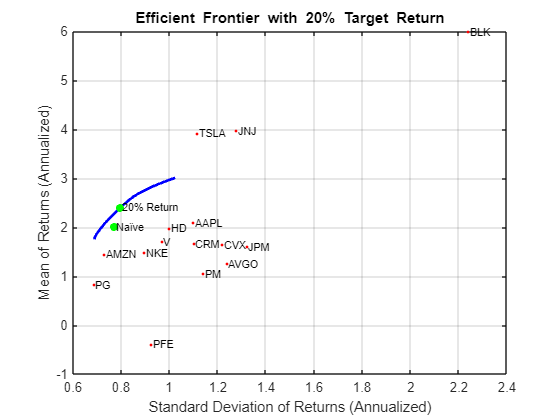

% Construct the Efficient Frontier using 30 Portfolios
pwgt = estimateFrontier(p_mean_var, 30);
[prsk, pret] = estimatePortMoments(p_mean_var, pwgt);

% Estimate the Frontier using the Target Return
targetReturn = 0.20;
twgt = estimateFrontierByReturn(p_mean_var, targetReturn);
[trsk, tret] = estimatePortMoments(p_mean_var, twgt);

% Extract asset moments from portfolio and store in m and cov
[m, c] = getAssetMoments(p_mean_var);

% Plot the optimal portfolio and efficient frontier
portfolio_plot('Efficient Frontier with 20% Target Return', ...
    {'line', prsk, pret}, ...
    {'scatter', nrsk, nret, {'Naïve'}}, ...
    {'scatter', trsk, tret, {sprintf('%g%% Return', 100*targetReturn)}}, ...
    {'scatter', sqrt(diag(c)), m, symbols, '.r'});

Considering that this is the Mean-Variance, we should also see what the return would like when maximizing the Sharpe Ratio.

% Estimate the Frontier using the Max Sharpe Ratio
wts = estimateMaxSharpeRatio(p_mean_var);
[sprsk, spret] = estimatePortMoments(p_mean_var, wts);

% Display the results
disp(strcat("Max Sharpe Ratio Expected Return: ", string(spret)));

Max Sharpe Ratio Expected Return: 0.23002


disp(strcat("Max Sharpe Ratio Risk: ", string(sprsk)));

Max Sharpe Ratio Risk: 0.26023


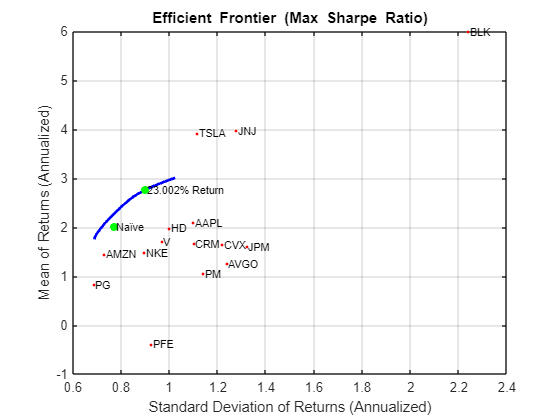

% Extract asset moments from portfolio and store in m and cov
[m_sp, c_sp] = getAssetMoments(p_mean_var);

% Plot the optimal portfolio and efficient frontier
portfolio_plot('Efficient Frontier (Max Sharpe Ratio)', ...
    {'line', prsk, pret}, ...
    {'scatter', nrsk, nret, {'Naïve'}}, ...
    {'scatter', sprsk, spret, {sprintf('%g%% Return', 100*spret)}}, ...
    {'scatter', sqrt(diag(c_sp)), m_sp, symbols, '.r'});

Next, let's draw the tangent line.

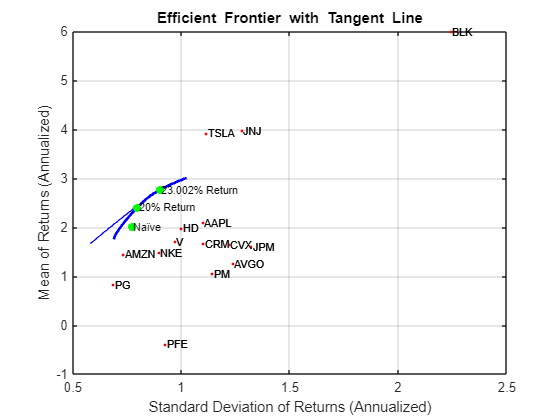

% Create a copy of the portfolio
portfolio_copy = setBudget(p_mean_var, 0, 1);

% Use it to estimate the new frontier
copy_wgt = estimateFrontier(portfolio_copy, 30);
[crsk, cret] = estimatePortMoments(portfolio_copy, copy_wgt);

clf;
portfolio_plot('Efficient Frontier with Tangent Line', ...
	{'line', prsk, pret}, ...
	{'line', crsk, cret, [], [], 1}, ...
	{'scatter', nrsk, nret, {'Naïve'}}, ...
    {'scatter', trsk, tret, {sprintf('%g%% Return', 100*targetReturn)}}, ...
    {'scatter', sprsk, spret, {sprintf('%g%% Return', 100*spret)}}, ...
	{'scatter', sqrt(diag(p_mean_var.AssetCovar)), m, symbols, '.r'}, ...
    {'scatter', sqrt(diag(c_sp)), m_sp, symbols, '.r'});

### Fama-French 3-Factor Model

We will apply the Fama-French 3-Factor model to the dataset to calculate the investment's return based on 3 factors: market risk, the degree to which small companies outperform large companies, and the degree to which high-value companies outperform low-value companies.


$$E[R] = r_{f} + \beta_{1}(r_{m} - r_{f}) + \beta_2(SMB) + \beta_{3}(HML) + \epsilon$$


We have extracted the Fama-French data from Yahoo Finance.

% Read the data from the file
F = readtable("fama_french_daily_updated.csv");

% Fit a linear regression model to the data
asset_return = fitlm(F(:, 2:end));
disp(asset_return);

Linear regression model:
    daily_return ~ 1 + Mkt_PM + SMB + HML

Estimated Coefficients:
                    Estimate         SE         tStat      pValue 
                   __________    __________    _______    ________

    (Intercept)    0.00059998    0.00040012     1.4995     0.13401
    Mkt_PM         8.7393e-05     0.0002957    0.29555     0.76763
    SMB             0.0012044    0.00056797     2.1206    0.034166
    HML            0.00060834    0.00035388      1.719    0.085872


Number of observations: 1170, Error degrees of freedom: 1166
Root Mean Squared Error: 0.0137
R-squared: 0.007,  Adjusted R-Squared: 0.00445
F-statistic vs. constant model: 2.74, p-value = 0.0422


Finally, let's visualize the weights. All weights should equal 1 in the end.

tBlotter = dataset({twgt(twgt > 0), 'Weight'}, 'obsnames', p_mean_var.AssetList(twgt > 0));

display_portfolio_weights(sprintf('Portfolio with %g%% Target Return', 100*targetReturn), tBlotter, false);

Portfolio with 20% Target Return
            Weight  
    TSLA     0.21542
    CVX         0.05
    JNJ         0.05
    AAPL        0.05
    JPM         0.05
    AVGO        0.05
    HD          0.05
    PG          0.05
    CRM         0.05
    PM          0.05
    PFE         0.05
    AMZN     0.10728
    NKE         0.05
    BLK     0.077298
    V           0.05



## The Black-Litterman Model

Now that we are done with the mean-variance model, we will proceed with the Black-Litterman model. The Black-Litterman takes into account not only risk and return, but also the investor's views regarding future market changes.


$$E[R] = [P^{T} \Omega^{-1}P + C^{-1}]^{-1}[P^{T} \Omega^{-1}q + C^{-1} \pi]$$


% We will calculate the returns of the stock prices same as before.
returns = tick2ret(T(:, 2:end), "Method", "continuous");
symbols = T.Properties.VariableNames(2:16);
m = mean(returns.Variables) * 252;

% Get the benchmark returns
sp500 = readtable("sp500.csv");
sp500_returns = sp500.daily_return;

For the Black-Litterman model to work properly, we need to incorporate our views into the investment process. We will assume three views:

- Blackrock is going to have 5% annual return with uncertainty 1e-5. This is a strong absolute view.

- Amazon is going to outperform Tesla by 5% annual return with uncertainty 1e-3. This is a weak relative view.

- JP Morgan Chase & Co. will have a 3% annual return with uncertainty 1e-3. This is a weak absolute view.

v = 3;  % total 3 views
P = zeros(v, 15);
q = zeros(v, 1);
Omega = zeros(v);
 
% View 1
P(1, symbols == "BLK") = 1; 
q(1) = 0.05;
Omega(1, 1) = 1e-5;

% View 2
P(3, symbols == "AMZN") = 1; 
P(3, symbols == "TSLA") = -1; 
q(3) = 0.05;
Omega(3, 3) = 1e-3;

% View 3
P(2, symbols == "JPM") = 1; 
q(2) = 0.03;
Omega(2, 2) = 1e-3;

% Visualize the returns
viewTable = array2table([P q diag(Omega)], 'VariableNames', ...
    [symbols "View_Return" "View_Uncertainty"]) 

viewTable = 3×17 table
    TSLA    CVX    JNJ    AAPL    JPM    AVGO    HD    PG    CRM    PM    PFE    AMZN    NKE    BLK    V    View_Return    View_Uncertainty
    ____    ___    ___    ____    ___    ____    __    __    ___    __    ___    ____    ___    ___    _    ___________    ________________

      0      0      0      0       0      0      0     0      0     0      0      0       0      1     0       0.05   

We notice that the stock returns that we have are daily returns whilst the views that we have are annual views. We convert the views to be on daily returns.

q = q/252; 
Omega = Omega/252;

We move on to calculate Sigma and C.

% Sigma is the covariance of the historical asset returns.
Sigma = cov(returns.Variables);
tau = 1/size(returns.Variables, 1);
C = tau*Sigma;

[wtsMarket, PI] = getMarketPortfolioAndImpliedReturn(returns.Variables, sp500_returns);

Now that we have all the variables that we need, we can proceed with applying the model. We will use the model to calculate the estimated mean and covariance.

% Calculate the estimated mean and covariance
mu_bl = (P'*(Omega\P) + inv(C)) \ ( C\PI + P'*(Omega\q));
cov_mu = inv(P'*(Omega\P) + inv(C));

% Display the results
disp(table(symbols', PI*252, mu_bl*252, 'VariableNames', ["Asset_Name", ...
    "Prior_Belief_of_Expected_Return", "Black_Litterman_Blended_Expected_Return"]));

    Asset_Name    Prior_Belief_of_Expected_Return    Black_Litterman_Blended_Expected_Return
    __________    _______________________________    _______________________________________

     {'TSLA'}                 0.12496                                0.10175                
     {'CVX' }                 0.10716                               0.084986                
     {'JNJ' }                 0.12087                               0.096781                
     {'AAPL'}                 0.13034                                0.11289                
     {'JPM' }                 0.11099                               0.084478                
     {'AVGO'}                0.099202                               0.087411                
     {'HD'  }                 0.11782                                0.10368                
     {'PG'  }                 0.10325                       

Let's compare the performance of the Black-Litterman Model with the performance of the Mean-Variance Model.

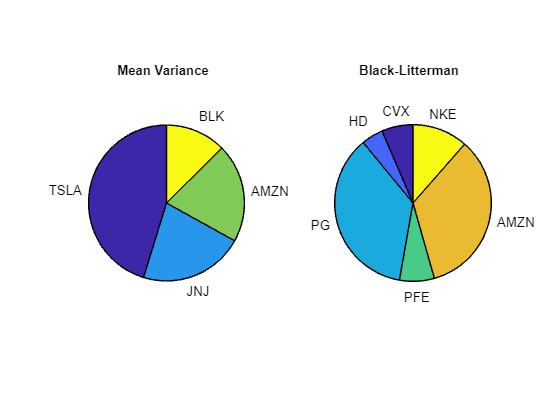

% Mean-Variance Model
port = Portfolio('NumAssets', length(symbols), 'lb', 0, 'budget', 1, 'Name', 'Mean Variance');
port = setAssetMoments(port, mean(returns.Variables) * 252, Sigma);
wts = estimateMaxSharpeRatio(port);

% Mean-Variance with Black-Litterman
portBL = Portfolio('NumAssets', length(symbols), 'lb', 0, 'budget', 1, 'Name', 'Black-Litterman');
portBL = setAssetMoments(portBL, mu_bl * 252, Sigma + (cov_mu * 252));  
wtsBL = estimateMaxSharpeRatio(portBL);

% Plotting Settings
ax1 = subplot(1,2,1);
idx = wts>0.001;
pie(ax1, wts(idx), symbols(idx));
title(ax1, port.Name ,'Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
idx_BL = wtsBL>0.001;
pie(ax2, wtsBL(idx_BL), symbols(idx_BL));
title(ax2, portBL.Name ,'Position', [-0.05, 1.6, 0]);

## Evaluating The Performance of The Models

We will employ a series of evaluation techniques to assess the performance of the Naïve, Mean-Variance, and Black-Litterman models. These evaluation techniques are the Sharpe Ratio and the Information Ratio. We will use the stock prices data for the same assets from January 1, 2024 till February 28, 2024.


$$SR = \frac{E[R_p] - r_f}{\sigma_p}$$



$$IR = \frac{R_p - R_B}{\sigma_{R_p - R_B}}$$


### The Naïve Model

Beginning with the Naïve model, we will apply all three methods to evaluate the performance of this model.

% Get the necessary data
Y = readtable("stock_data_2024.csv");
returns_2024 = tick2ret(Y(:, 2:end), "Method", "continuous");
symbols = Y.Properties.VariableNames(2:end);

% Get the benchmark data
B = readtable("sp500_2024.csv");
sp500_returns_2024 = B.daily_return;
sp500_mean_returns_2024 = mean(sp500_returns_2024) * 42;
sp500_risk_2024 = std(sp500_returns_2024);

We re-create the Naïve portfolio using the new returns. From these returns, we get the expected return of the naïve portfolio and risk.

% Create a new portfolio object
% We'll call it p_mean_var_2024 because we'll use it later
p_mean_var_2024 = Portfolio('AssetList', symbols, 'RiskFreeRate', 0.05);
m_2024 = mean(returns_2024.Variables) * 42;
c_2024 = cov(returns_2024.Variables) * 42;

p_mean_var_2024 = setAssetMoments(p_mean_var_2024, m_2024, c_2024);

% Create the naive portfolio
p_naive_2024 = setInitPort(p_mean_var_2024, 1/p_mean_var_2024.NumAssets);
[nrsk, nret] = estimatePortMoments(p_naive_2024, p_naive_2024.InitPort);

naive_port_return = sum(1/15 * nret);
naive_port_risk = sqrt(nrsk);

% Sharpe Ratio
Sharpe = (naive_port_return - 0.05)/naive_port_risk;
disp(strcat("Sharpe Ratio of Naïve Model: ", string(Sharpe)));

Sharpe Ratio of Naïve Model: -0.22197


% Information Ratio
trackingError = std(naive_port_return - sp500_mean_returns_2024);
IR = (naive_port_return - sp500_mean_returns_2024)/trackingError;
disp(strcat("Information Ratio of Naïve Model: ", string(IR)));

Information Ratio of Naïve Model: -Inf


### The Mean-Variance Model

% Get the mean and covariance of the mean-variance portfolio
[mrsk, mret] = estimatePortMoments(p_mean_var_2024, twgt);

mean_var_port_return = sum(twgt * mret);
mean_var_port_risk = sqrt(mrsk);

% Sharpe Ratio
Sharpe = (mean_var_port_return - 0.05)/mean_var_port_risk;
disp(strcat("Sharpe Ratio of Mean-Variance Model: ", string(Sharpe)));

Sharpe Ratio of Mean-Variance Model: -0.1332


% Information Ratio
trackingError = std(mean_var_port_return - sp500_mean_returns_2024);
IR = (mean_var_port_return - sp500_mean_returns_2024)/trackingError;
disp(strcat("Information Ratio of Mean-Variance Model: ", string(IR)));

Information Ratio of Mean-Variance Model: -Inf


### The Black-Litterman Model

v = 3;  % Same 3 views
P = zeros(v, 15);
q = zeros(v, 1);
Omega = zeros(v);
 
% View 1
P(1, symbols == "BLK") = 1; 
q(1) = 0.05;
Omega(1, 1) = 1e-5;

% View 2
P(3, symbols == "AMZN") = 1; 
P(3, symbols == "TSLA") = -1; 
q(3) = 0.05;
Omega(3, 3) = 1e-3;

% View 3
P(2, symbols == "JPM") = 1; 
q(2) = 0.03;
Omega(2, 2) = 1e-3;

% q and Omega
q = q/42; 
Omega = Omega/42;

% Sigma and C
Sigma = cov(returns_2024.Variables);
tau = 1/size(returns_2024.Variables, 1);
C = tau*Sigma;

% Get the required data
[wtsMarket, PI] = getMarketPortfolioAndImpliedReturn(returns_2024.Variables, sp500_returns_2024);

% Calculate the mean return and covariance
mu_bl_2024 = (P'*(Omega\P) + inv(C)) \ ( C\PI + P'*(Omega\q));
cov_mu_2024 = inv(P'*(Omega\P) + inv(C));

% Portfolio Return and Risk
bl_port_return = sum(sum(wtsBL * transpose(mu_bl_2024)));
bl_port_risk = sum(std(transpose(wtsBL) * cov_mu_2024));

% Sharpe Ratio
Sharpe = (bl_port_return - 0.05)/bl_port_risk;
disp(strcat("Sharpe Ratio of Black-Litterman: ", string(Sharpe)));

Sharpe Ratio of Black-Litterman: -85199.0933


% Information Ratio
trackingError = std(bl_port_return - sp500_mean_returns_2024);
IR = (bl_port_return - sp500_mean_returns_2024)/trackingError;
disp(strcat("Information Ratio of Black-Litterman: ", string(IR)));

Information Ratio of Black-Litterman: -Inf
